# Sistemas Realimentados

# Exemplo de uso de live scripts no Matlab

## Nome: (coloque seu nome aqui)

## Título: Exemplo de uso do livre script

**Atenção:**

Evitar erros ortográficos ao escrever as respostas.

Aguardar gerar o arquivo pdf, abrir e conferir, e só então depositar no google class.

Execute inicialmente uma seção de cada vez (Run Section).

Ao final, dar o comando run para gerar o relatório em pdf a ser entregue.

## Data e hora do relatório e geração do relatório

datetime('now')


Substitua seu valor de I, informado pelo professor.

I=1; % Coloque seu valor de I : parametro inidivual
pn=init(I);

## 1. Resposta a partir de figuras dadas

Na figura 1 é mostrado o diagrama de blocos de um sistema de controle. Pode-se apresentar também conteúdos sobre a figura para ajudar na execução da atividade. Por exemplo, que a FT de malha fechada é dada por $\frac{Y\left(s\right)}{R\left(s\right)}=\frac{C\left(s\right)G\left(s\right)}{1+C\left(s\right)G\left(s\right)}$.

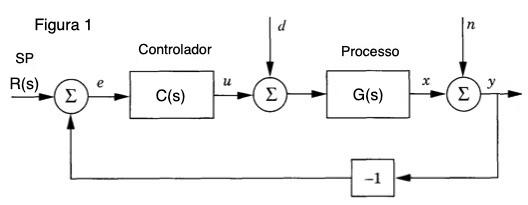

Faz-se então perguntas sobre a figura.

1.1 Obtenha  $\frac{Y\left(s\right)}{N\left(s\right)}$.

Resposta : $\frac{Y\left(s\right)}{N\left(s\right)}=\frac{1}{1+C\left(s\right)G\left(s\right)}$  (escrever a equação em Latex)

1.2 Se for usando um controlador C(s) PI e uma FT G(s) de ordem 1, qual a ordem de $\frac{Y\left(s\right)}{R\left(s\right)}$?

Resposta: ....(analisar variáveis no workspace, escrever texto)

## Resposta à figura dada consultando uma referência.

2. Relacione os elementos do diagrama de blocos mostrado na figura 2 ao sistema de controle de velocidade descrito no livro [Ogata](https://drive.google.com/file/d/1SgVr6PlMiKs3IRNhhIN1-cDBJWfP1bZ1/view?usp=sharing).   

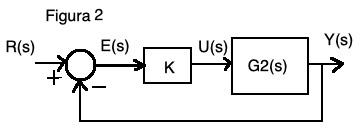

Resposta: (escrever texto)

## Escolha de parâmetros que atendam requisitos dados. Testa-se valores no live script observando o resultado.

**Sobre o comando feedback:**

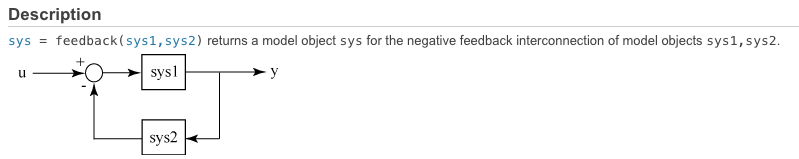

3. Seja a FT de MA $G\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}=\frac{K}{s\left(s+p_n \right)}$. 

3.1 Escolha um valor de ganho $K$ tal que o sistema seja estável e com pouca sobreelevação, verificando o amortecimento e frequência natural dos polos.

K=50; % Escolha um valor para K
g=tf(K,[1 pn 0]);
m=feedback(g,1)
p=pole(m)
[wn,zeta]=damp(m)

3.2 Qual o tipo deste sistema?

Resposta:

3.3 Obtenha Y(s)/R(s)

Resposta:

gry=feedback(g,1)

3.3 Obtenha E(s)/R(s)

gre=feedback(1,g)

3.4 Mostre E(s) e Y(s) para uma entrada degrau unitário R(s).

figure;
step(gry,gre)

## Realização de análises variando um parâmetro e gerando uma tabela.

4. Monte a Tabela 1 com 5 valores de ganho K, mostrando os polos resultantes, o amortecimento $\zeta \;$e a frequência natural não amortecida $w_n$. Escolha os ganhos de modo que o amortecimento vá de 0.1 a 0.8.

clear polos wn zeta;
K=[1 2 4 6 8]; % Escolher os 5 valores adequadamente
for i=1:5
    m=feedback(K(i)*g,1);
    polos(:,i)=pole(m);
    [w0,z0]=damp(m);
    wn(i,1)=w0(1);
    zeta(i,1)=z0(1);
end
polos=polos';
Tabela1=table(polos,wn,zeta)

4.1 Comente o gráfico de $\zeta \;$versus $w_n$.

plot(zeta,wn);xlabel('\zeta');ylabel('w_n');

## Análise de um gráfico gerado via simulação.

5. Seja a FT de MA $G\left(s\right)=\frac{p_n }{s^2 +3s+p_n }$ e sua resposta ao degrau mostrada na figura 3. 

figure;
G=tf(pn,[1 0.6*sqrt(pn) pn]);
step(G);title('Figura 3: Resposta ao degrau unitário')

6.1 Obtenha da figura o valor de sobreelevação, tempo de subida e tempo de estabelecimento, escrevendo abaixo seus valores.:

## Análise de gráficos gerados por expressões

7. Execute o código abaixo e observe a figura 4, que gera os valores de sobreelevacão UP correspondentes aos valores de amortecimento $\zeta$(zeta) através da equação $\textrm{UP}=100e^{-\zeta \pi /\sqrt{1-\zeta^2 }}$. Para dúvidas, ler [livro](https://drive.google.com/file/d/19Hub5F7T0eJ_jnDahAffTpmmUpmCoKIj/view?usp=share_link).

zeta=linspace(0.01,0.95,20);
for i=1:20
UP(i)=100*exp(-zeta(i)*pi/(sqrt(1-zeta(i)^2)));
end
figure
plot(zeta,UP);title('Figura 4. - Sobreelevação UP e amortecimento \zeta ');
xlabel('\zeta');ylabel('UP')

7.1 Explique a relação entre o amortecimento e a sobreelevação.

## Análise via comandos dados no workspace.

8. Dê o comando help feedback no workspace.

8.1 Explique como ele funciona.

8.2 Explique como obter $\frac{Y\left(s\right)}{R\left(s\right)}$ na Figura 1 usando este comando.